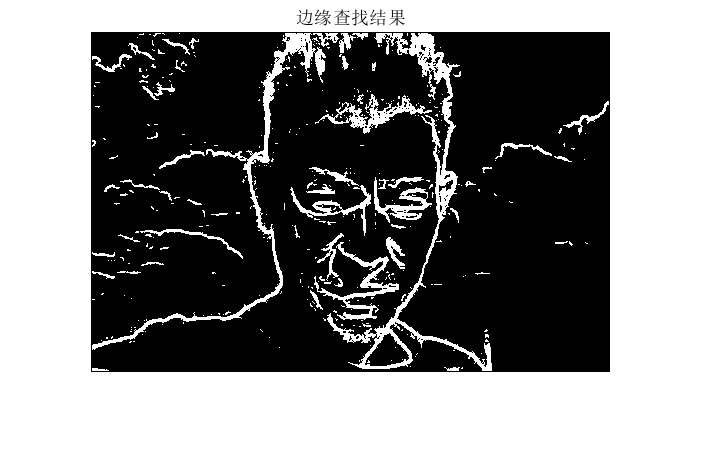

clc;clear;close all;

%图像读取
image_water=imread("03-大海背景.jpg");
image_people=imread("03-刘德华.jpg");
image_people=double(image_people);%化为double变量便于计算


%查找边缘
tmp=zeros(size(rgb2gray(image_people)));
for i=2:339
    for j=2:518
        tmp(i,j)=change(image_people,i,j);
    end
end
tmp=uint8(tmp);
figure;
imshow(tmp);
title("边缘查找结果");

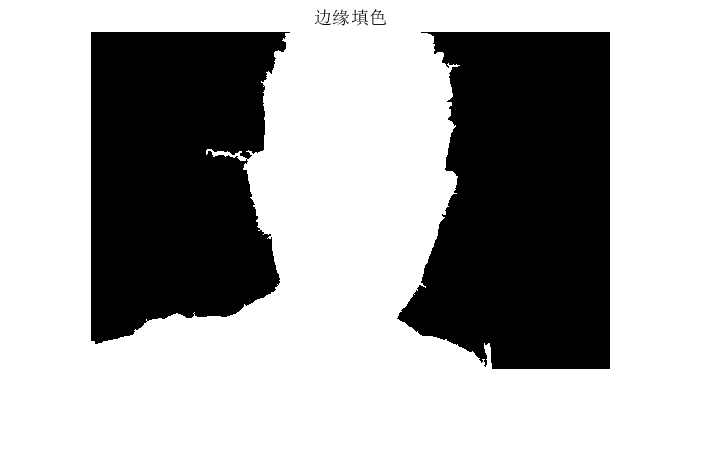




BW2=tmp;
%使用划线，便于之后的区域填充
BW2(1:4,200:330)=255;
BW2(338:340,:)=255;
BW2(310:340,1:4)=255;
BW2 = imfill(BW2);

%对填色后的边缘查找最大连通域
L = bwlabel(BW2);% 对连通区域进行标记
stats = regionprops(L);
Ar = cat(1, stats.Area);
ind = find(Ar ==max(Ar));%找到最大连通区域的标号
BW2(find(L~=ind))=0;%将其他区域置为0
figure,imshow(BW2);%显示最大联通区域
title("边缘填色");

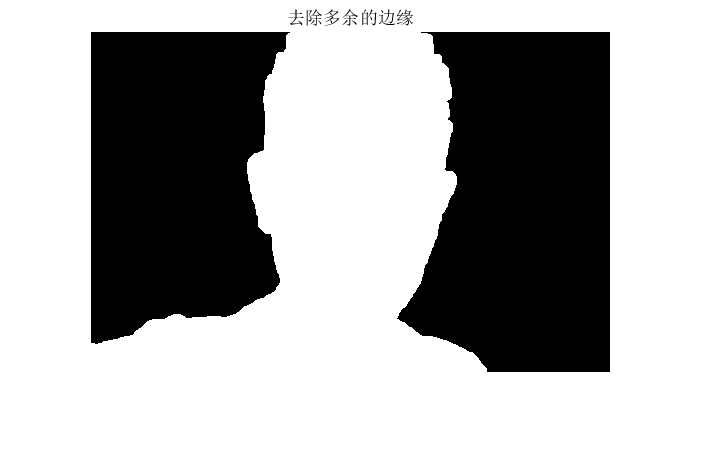







%对图像进行开运算，去除云雾的边缘
se=strel('ball',4,2);
bw=imopen(BW2, se);  
figure;
imshow(bw);
title("去除多余的边缘");

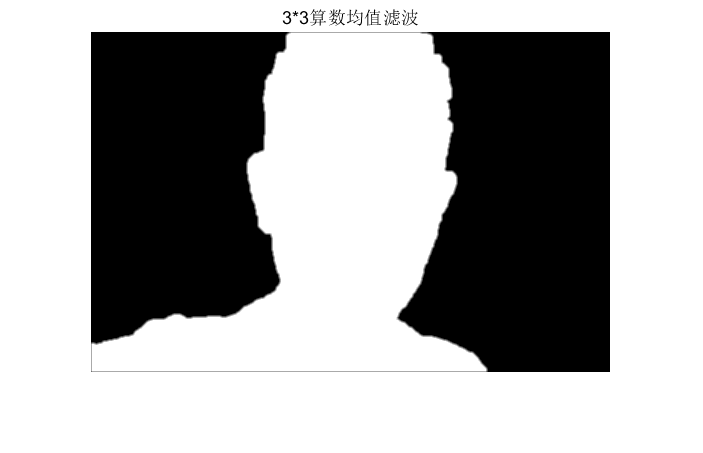




%对裁剪的图进行边缘柔化，使得结果图更平滑
I_3=fspecial('average',[3,3]);%3*3均值滤波
bw=imfilter(bw,I_3);
imshow(bw,[]);title('3*3算数均值滤波');

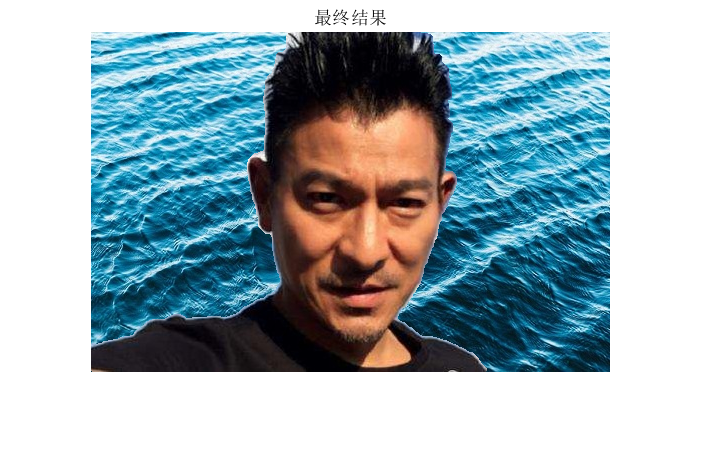




%产生一个空白背景图并进行裁剪
image_people=uint8(image_people);
output=image_water;
output(:,:,1)=image_water(:,:,1).*((255-bw)/255)+image_people(:,:,1).*(bw/255);
output(:,:,2)=image_water(:,:,2).*((255-bw)/255)+image_people(:,:,2).*(bw/255);
output(:,:,3)=image_water(:,:,3).*((255-bw)/255)+image_people(:,:,3).*(bw/255);
figure;
imshow(output);
title('最终结果');















%边缘查找函数（计算三通道像素插值绝对值的和）

function ch=change(I,i,j)
    ch=ones(3,3,3);
    ch(:,:,1)=I(i,j,1);
    ch(:,:,2)=I(i,j,2);
    ch(:,:,3)=I(i,j,3);
    
    %计算像素相似度
    ch=sum(sum(sum(abs(I(i-1:i+1,j-1:j+1,:)-ch))));
    if ch>245
        ch=255;
    else
        ch=0;
    end
end
        
